# Dummy maps for linear effects of stimlus intensity 

Model (6cond)

parameter:

- 6 Stimulus onset

- `    cue ``H``igh x stim ``H``igh (onset03_stim)`

- `    cue ``H``igh x stim ``M``ed`

- `    cue ``H``igh x stim ``L``ow`

- `    cue ``L``ow x stim ``H``igh`

- `    cue ``L``ow x stim ``M``ed`

- `    cue ``L``ow x stim ``L``ow`

- `C``ue: onset01_cue`

- `E``xpect rating: onset02_ratingexpect, pmod_expectRT`

- `O``utcome rating: onset04_ratingoutcome, pmod_outcomeRT`

- Motion covariate: 24DOF + CSF

- Spike, as many spikes detected by fmriprep (FD spike threshold 0.9)

# Pain only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

#### Pain only :: load dataset

clear all;
close all;

contrast_of_interest = 'P_simple_STIM_stimlin_high_gt_low'

contrast_of_interest = 'P_simple_STIM_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_STIM_cue_high_gt_low','V_PC_CUE_STIM_cue_high_gt_low','C_PV_CUE_STIM_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_STIM_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_STIM_cue_high_gt_low',...% cue epoch dummy

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32347188 bytes
Loading image number:    81
Elapsed time is 3.782195 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7693324  Bit rate: 22.88 bits


#### Pain only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:41:46 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### Pain only :: Plot diagnostics, before l2norm

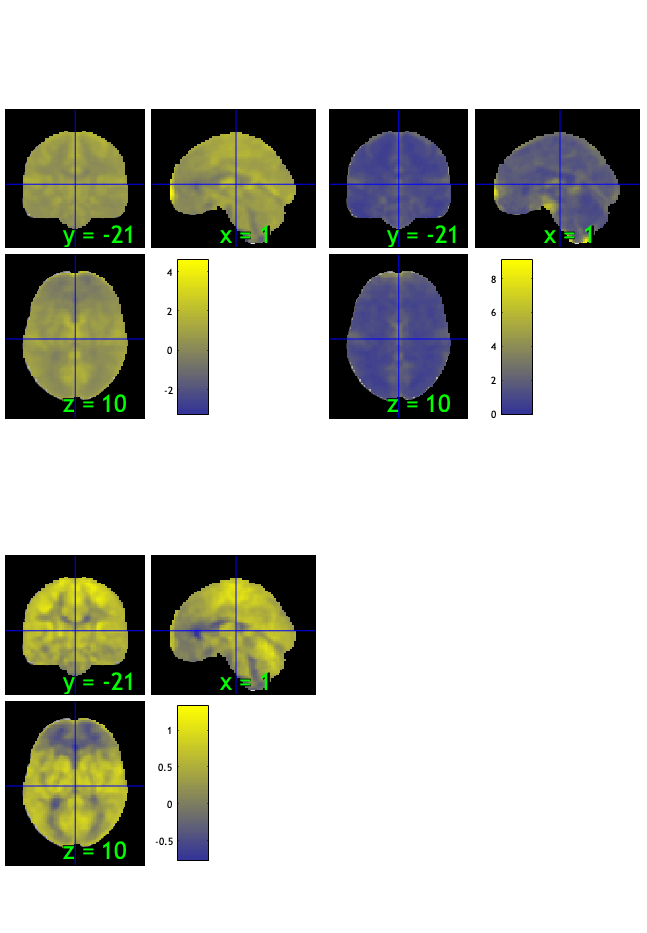

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 19.75%
Expected 4.05 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 5 images		Cases 44 51 55 59 62 
Uncorrected: 9 images		Cases 1 17 24 36 44 51 55 59 62 

Retained 10 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 54.32%
Expected 4.05 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 55 

Mahalanobis (cov and corr, q<0.05 corrected):
  5 images 
                               Outlier_count    Percentage
                    

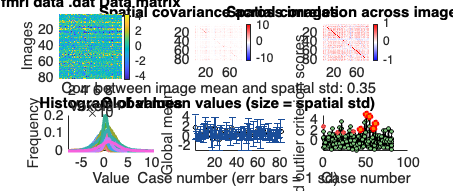

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:42:13 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

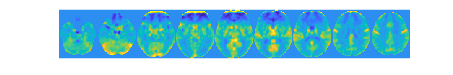

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain only :: run robfit

set(gcf,'Visible','on');
figure ('Visible', 'on');
drawnow, snapnow;


#### Pain only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 81


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 5 participants, size is now 76


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... …"    "participants that are outliers:... …"    "participants that are outliers:... …"    "participants that are outliers:... …"    "participants that are outliers:... …"



disp(n);

    {'sub-0084'}    {'sub-0093'}    {'sub-0098'}    {'sub-0102'}    {'sub-0106'}



#### Pain only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


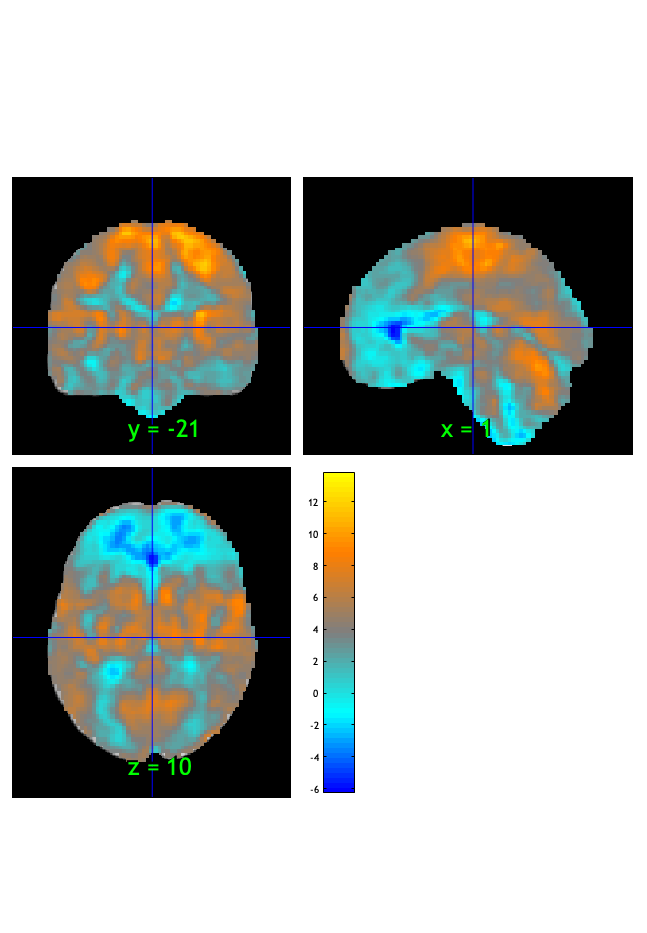

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:42:18 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.037489

Image   1
 22 contig. clusters, sizes   1 to 74696
Positive effect: 73162 voxels, min p-value: 0.00000000
Negative effect: 1700 voxels, min p-value: 0.00000000


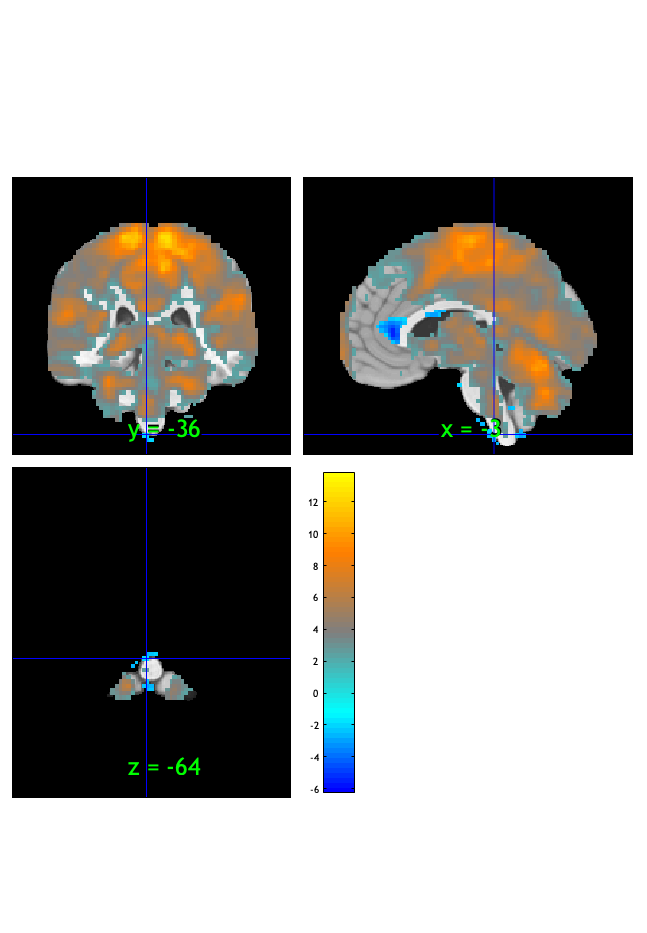

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:42:20 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000483

Image   1
 44 contig. clusters, sizes   1 to 47695
Positive effect: 48055 voxels, min p-value: 0.00000000
Negative effect: 140 voxels, min p-value: 0.00000000


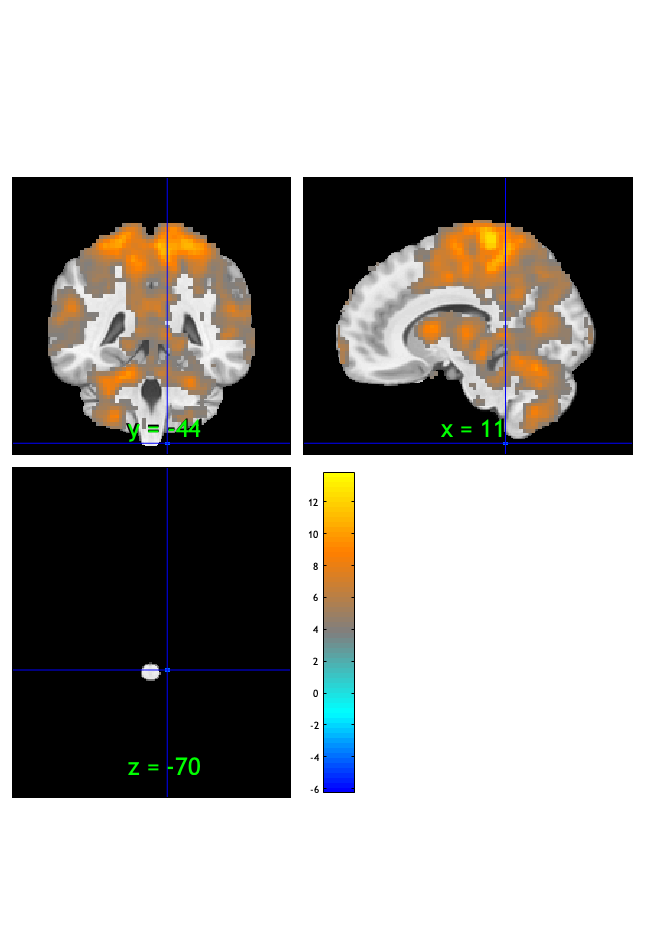

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:42:21 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


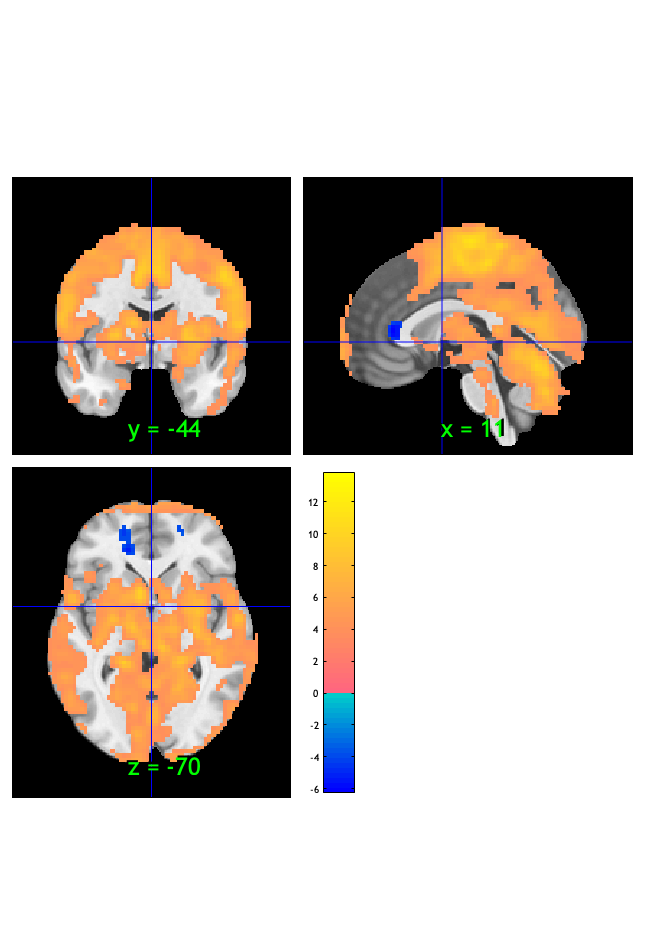

orthviews(fdr_t);

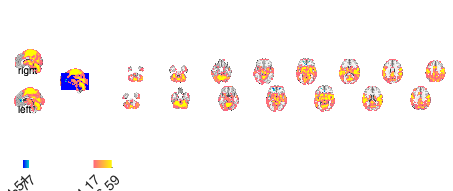

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 1262 voxels displayed, 46933 not displayed on these slices
sagittal montage: 1302 voxels displayed, 46893 not displayed on these slices
sagittal montage: 1169 voxels displayed, 47026 not displayed on these slices
axial montage: 8218 voxels displayed, 39977 not displayed on these slices
axial montage: 8914 voxels displayed, 39281 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

write(fdr_t, 'fname', strcat('/Users/h/Desktop/', contrast_of_interest, '_fdr_t.nii'), 'overwrite');

Writing: 
/Users/h/Desktop/P_simple_STIM_stimlin_high_gt_low_fdr_t.nii


#### Pain only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high    
    _________    ______________    __________    _________________

    -0.15044     {'trait'     }     0.26578      {'motor'        }
    -0.14608     {'disorder'  }     0.25892      {'movements'    }
    -0.14491     {'affect'    }     0.23558      {'sensorimotor' }
     -0.1427     {'judgment'  }     0.21686      {'finger'       }
     -0.1421     {'depression'}     0.21401      {'hand'         }
    -0.13535     {'face'      }     0.19734      {'somatosensory'}
    -0.13312     {'affective' }      0.1944      {'muscle'       }
    -0.13258     {'social'    }     0.19315      {'execution'    }
    -0.13136     {'work'      }     0.19096      {'sensory'      }
    -0.13021     {'face

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain only :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.0034	0.5794	0.5639	0.0000	
Cog Wholebrain	0.0128	3.3428	0.0013	1.0000	**
Emo Wholebrain	-0.0147	-2.7350	0.0077	1.0000	**
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    _______    _________    ________

    {'Pain Wholebrain'}    0.0034408     0.0060055    0.57294      0.56829     0.06366
    {'Cog Wholebrain' }     0.012768     0.0038197     3.3427    0.0012638     0.37141
    {'Emo Wholebrain' }    -0.014692     0.0053736    -2.7341    0.0076983    -0.30379



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [19.0001 20.0001 21.0001]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    _______    _________    ________

    {'Pain Wholebrain'}    0.0068114     0.0057995     1.1745      0.24368      0.1305
    {'Cog Wholebrain' }     0.011685      0.003536     3.3047    0.0014241     0.36719
    {'Emo Wholebrain' }    -0.017292     0.0052397    -3.3001    0.0014448    -0.36668



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [22.0001 23.0001 24.0001]


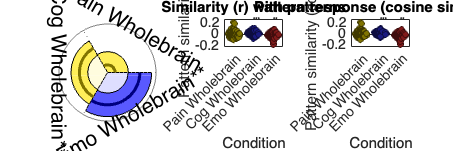

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

#### Vicarious only :: load dataset

clear all;
close all;

contrast_of_interest = 'V_simple_STIM_stimlin_high_gt_low'

contrast_of_interest = 'V_simple_STIM_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32347188 bytes
Loading image number:    81
Elapsed time is 3.451634 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7728078  Bit rate: 22.88 bits


#### Vicarious only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:43:19 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious only :: Plot diagnostics, before l2norm

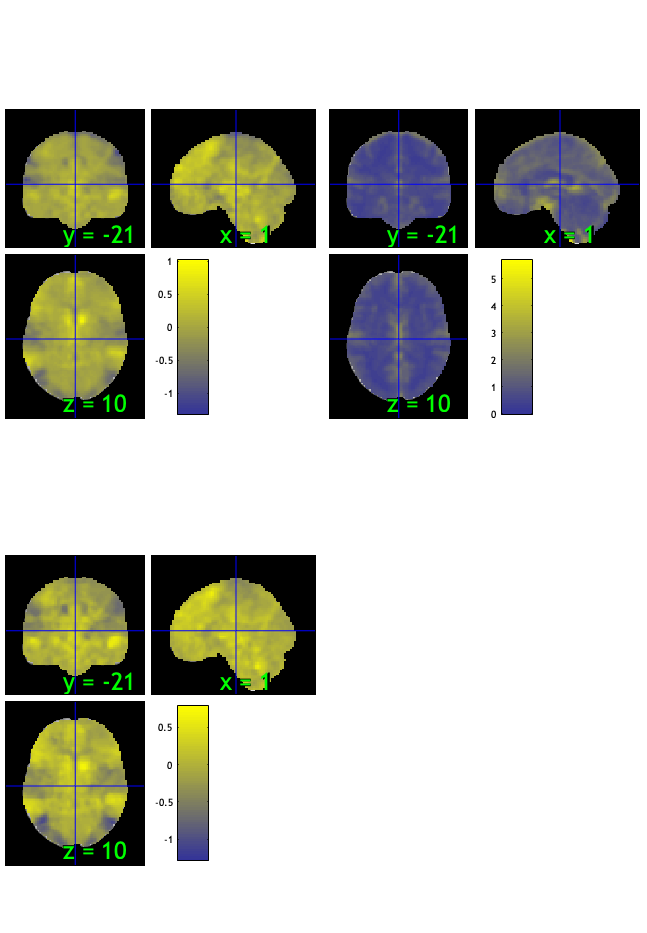

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 29.63%
Expected 4.05 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 46 55 
Uncorrected: 5 images		Cases 45 46 55 66 73 

Retained 12 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 53.09%
Expected 4.05 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 41 46 75 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

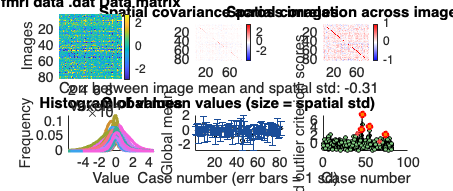

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:43:55 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious only :: run robfit

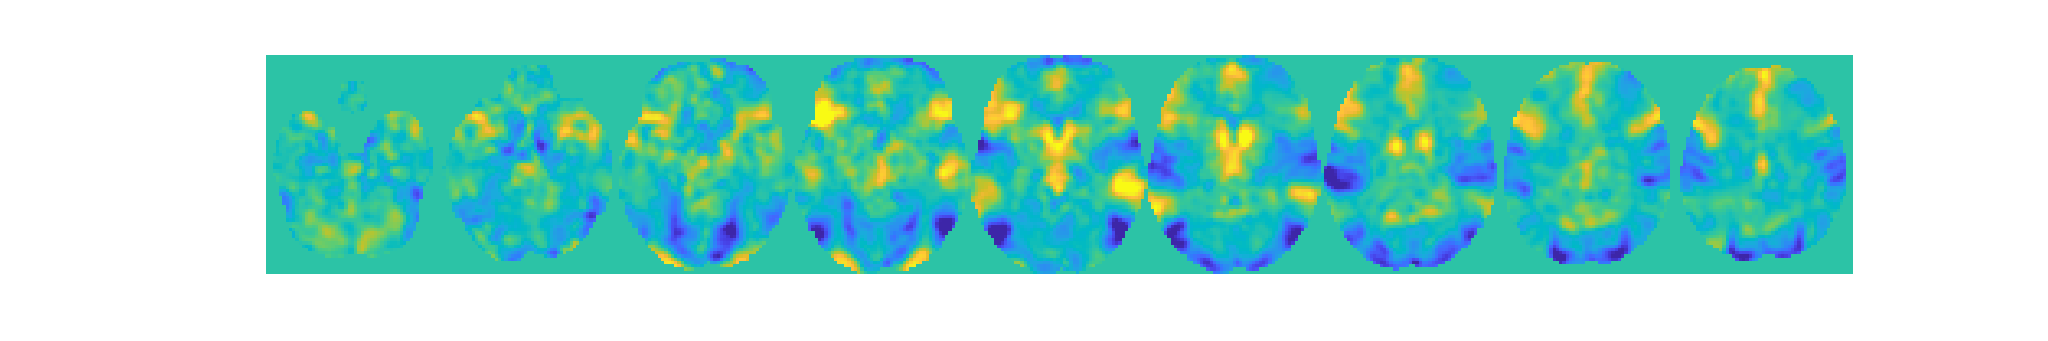

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 81


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 77


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0085"    "participants that are outliers:... sub-0086"    "participants that are outliers:... sub-0098"    "participants that are outliers:... sub-0123"



disp(n);

    {'sub-0085'}    {'sub-0086'}    {'sub-0098'}    {'sub-0123'}



#### Vicarious only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


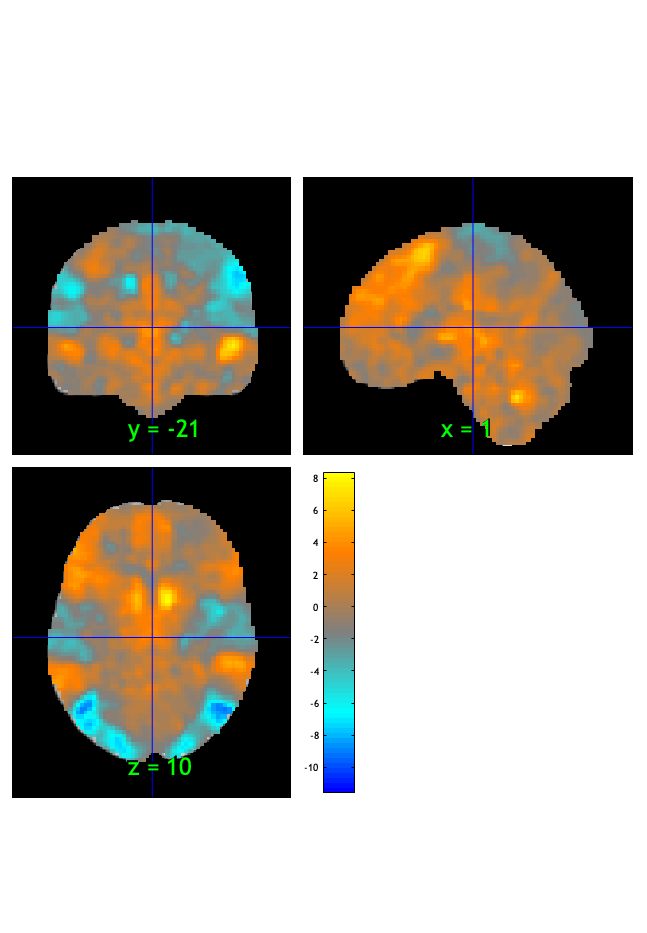

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:44:00 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.010466

Image   1
 85 contig. clusters, sizes   1 to 7246
Positive effect: 8403 voxels, min p-value: 0.00000000
Negative effect: 12496 voxels, min p-value: 0.00000000


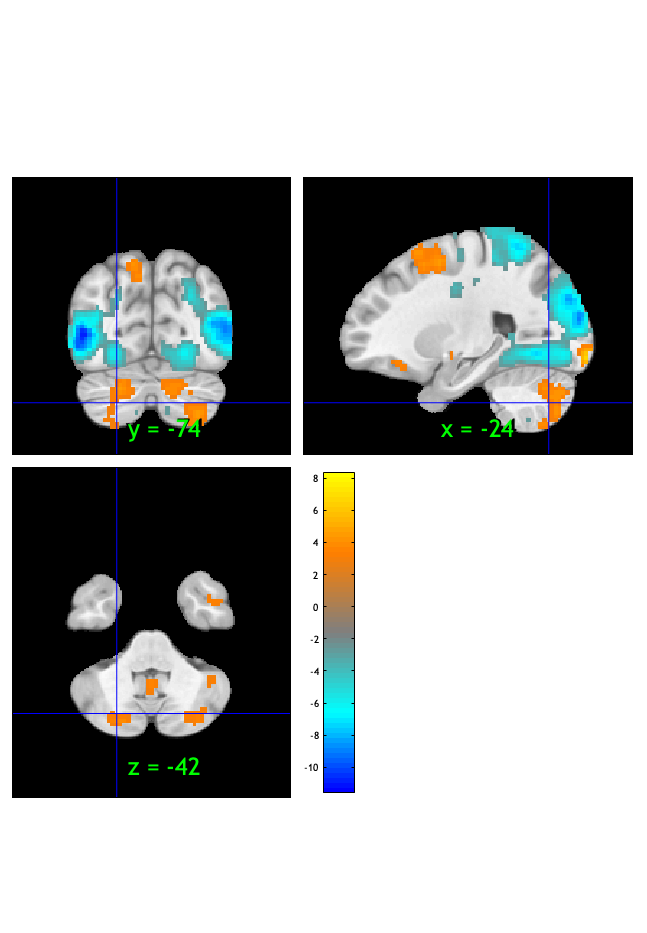

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:44:01 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


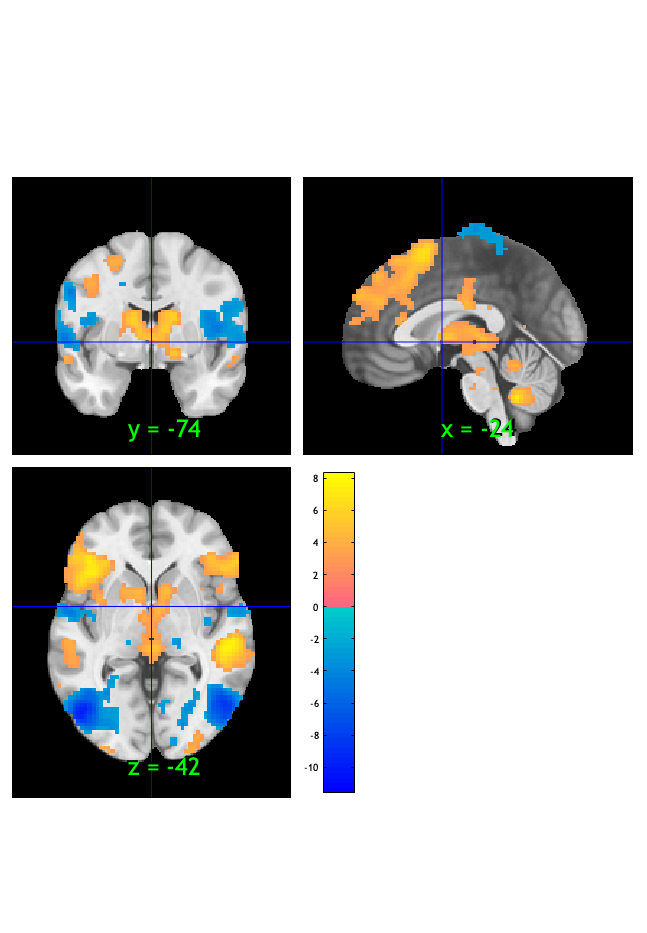

orthviews(fdr_t);

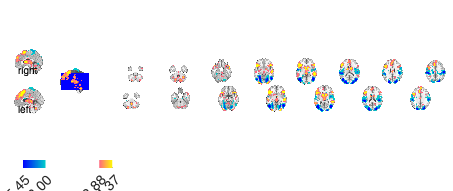

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 418 voxels displayed, 20481 not displayed on these slices
sagittal montage: 381 voxels displayed, 20518 not displayed on these slices
sagittal montage: 420 voxels displayed, 20479 not displayed on these slices
axial montage: 3720 voxels displayed, 17179 not displayed on these slices
axial montage: 3986 voxels displayed, 16913 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

#### Vicarious only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low      testr_high     words_high  
    _________    _____________    __________    _____________

    -0.36959     {'motion'   }     0.26848      {'verb'     }
    -0.34729     {'visual'   }     0.26069      {'verbal'   }
    -0.32659     {'spatial'  }     0.22662      {'word'     }
    -0.30018     {'hand'     }     0.21893      {'retrieval'}
    -0.29219     {'tactile'  }      0.2102      {'sentences'}
    -0.29088     {'shape'    }     0.20946      {'reward'   }
    -0.26982     {'object'   }      0.2061      {'semantic' }
    -0.26442     {'objects'  }     0.20225      {'memory'   }
    -0.26434     {'movements'}      0.1974      {'affect'   }
    -0.26428     {'eye'      }     0.19329      {'language' }



Vicarious only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0085	-1.3495	0.1810	0.0000	
Cog Wholebrain	-0.0033	-0.8503	0.3977	0.0000	
Emo Wholebrain	0.0110	1.6428	0.1044	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P       Cohens_d 
    ___________________    __________    _________    ________    _______    _________

    {'Pain Wholebrain'}    -0.0084655    0.0062725     -1.3496    0.18094     -0.14996
    {'Cog Wholebrain' }    -0.0033137    0.0038993    -0.84981    0.39797    -0.094424
    {'Emo Wholebrain' }       0.01098    0.0066822      1.6432    0.10427      0.18258



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [19.0002 20.0002 21.0002]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d 
    ___________________    __________    _________    ________    ________    _________

    {'Pain Wholebrain'}    -0.0085011    0.0061335      -1.386     0.16959       -0.154
    {'Cog Wholebrain' }    -0.0032206    0.0036095    -0.89227     0.37493    -0.099141
    {'Emo Wholebrain' }      0.011112    0.0065413      1.6987    0.093253      0.18875



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [22.0002 23.0002 24.0002]


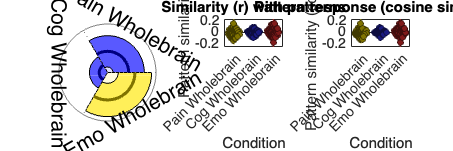

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

#### Cognitive only :: load dataset

clear all;
close all;

contrast_of_interest = 'C_simple_STIM_stimlin_high_gt_low'

contrast_of_interest = 'C_simple_STIM_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32347188 bytes
Loading image number:    81
Elapsed time is 3.219670 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7722707  Bit rate: 22.88 bits


#### Cognitive only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:44:58 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### Cognitive only :: Plot diagnostics, before l2norm

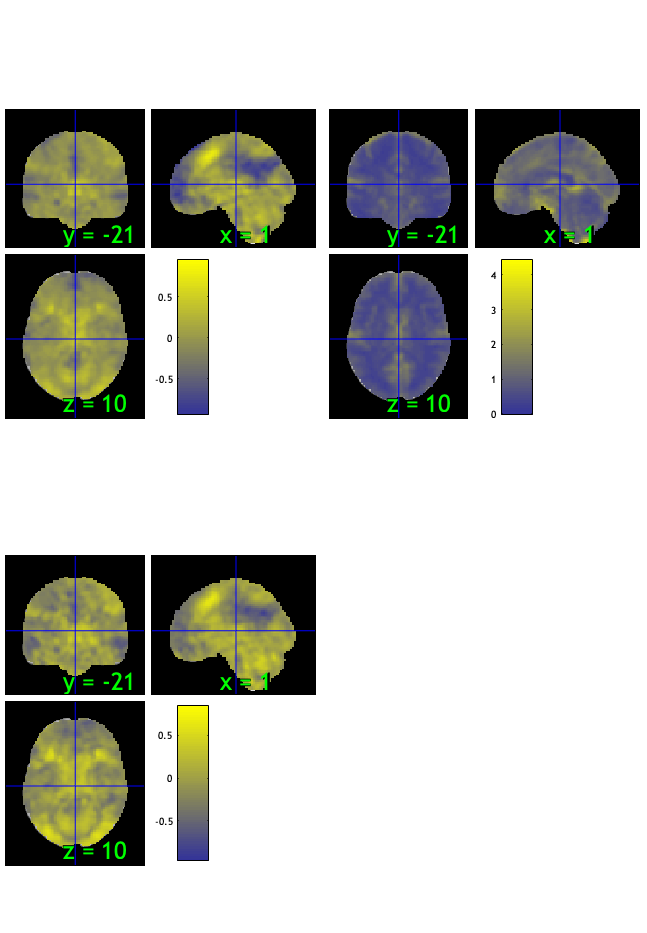

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 34.57%
Expected 4.05 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 2 images		Cases 46 71 
Uncorrected: 9 images		Cases 2 20 46 51 58 68 71 73 78 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 53.09%
Expected 4.05 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               <

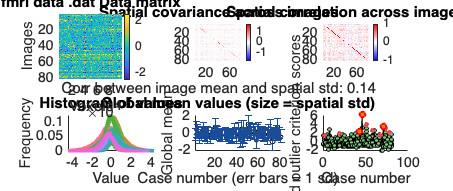

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:45:29 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive only :: run robfit

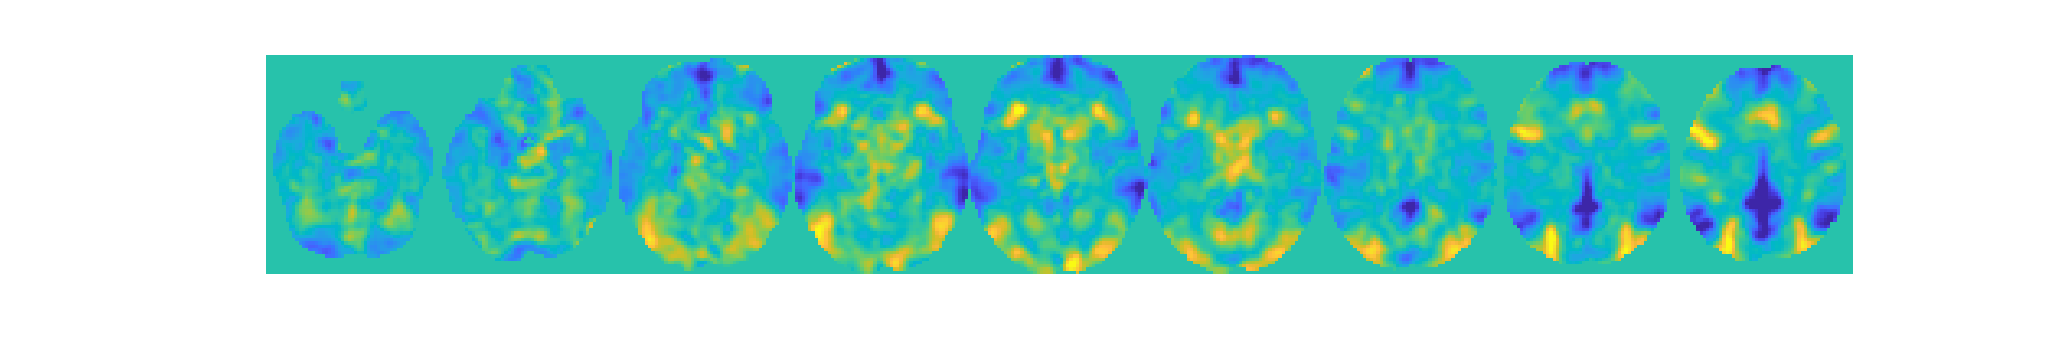

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 81


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 78


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0082"    "participants that are outliers:... sub-0086"    "participants that are outliers:... sub-0120"



disp(n);

    {'sub-0082'}    {'sub-0086'}    {'sub-0120'}



#### Cognitive only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


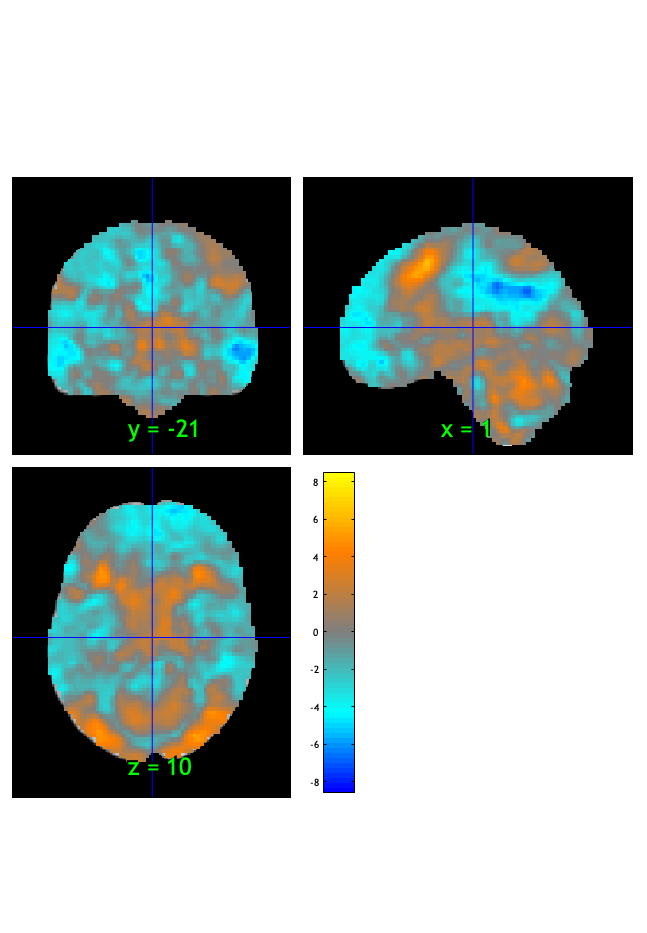

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:45:34 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.013062

Image   1
 99 contig. clusters, sizes   1 to 11448
Positive effect: 8743 voxels, min p-value: 0.00000000
Negative effect: 17338 voxels, min p-value: 0.00000000


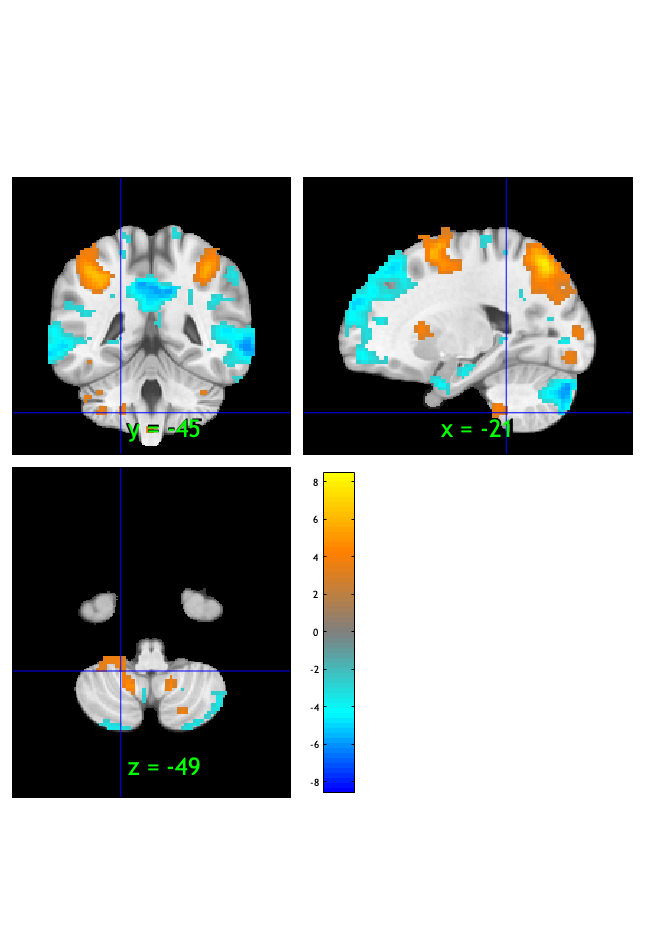

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:45:35 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


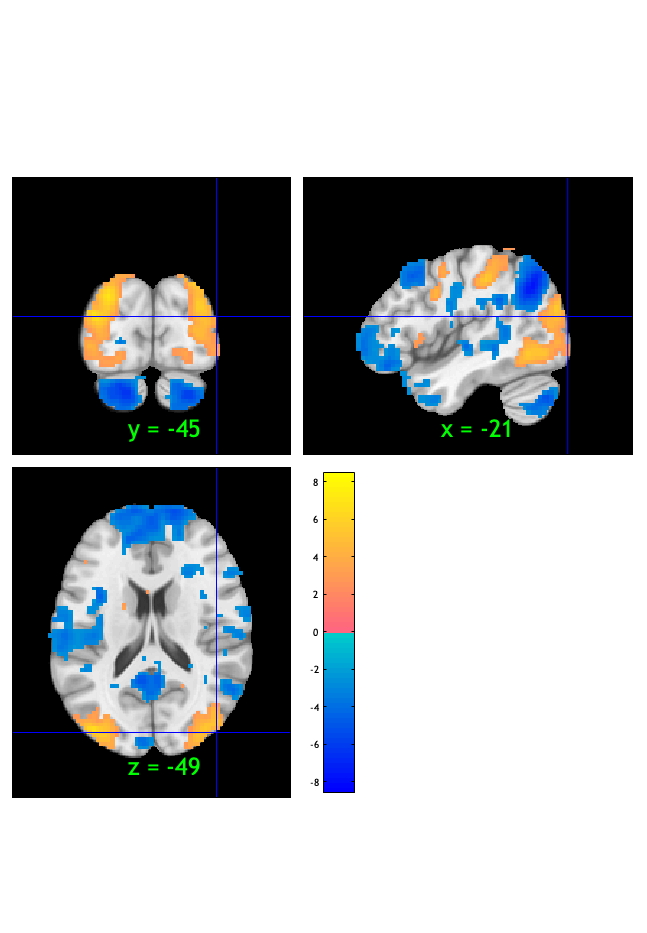

orthviews(fdr_t);

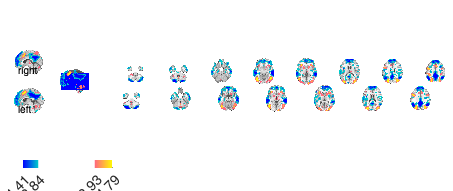

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 675 voxels displayed, 25406 not displayed on these slices
sagittal montage: 571 voxels displayed, 25510 not displayed on these slices
sagittal montage: 688 voxels displayed, 25393 not displayed on these slices
axial montage: 5069 voxels displayed, 21012 not displayed on these slices
axial montage: 5439 voxels displayed, 20642 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;



#### Cognitive only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low         words_low         testr_high       words_high   
    _________    ___________________    __________    ________________

     -0.3226     {'person'         }     0.36291      {'visual'      }
    -0.30492     {'trait'          }     0.31146      {'eye'         }
    -0.30037     {'default'        }     0.27609      {'target'      }
    -0.29069     {'social'         }     0.27074      {'letter'      }
    -0.28777     {'self'           }     0.26733      {'maintenance' }
    -0.28661     {'personal'       }      0.2638      {'saccade'     }
    -0.27135     {'positive'       }     0.25754      {'visuospatial'}
     -0.2707     {'rating'         }     0.24665      {'working'     }
     -0.2667     {'selfreferential'}     0.24524  

Cognitive only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0030	-0.5384	0.5918	0.0000	
Cog Wholebrain	-0.0222	-4.5116	0.0000	1.0000	***
Emo Wholebrain	0.0227	3.5107	0.0007	1.0000	***
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d 
    ___________________    __________    _________    ________    __________    _________

    {'Pain Wholebrain'}    -0.0030046    0.0055897    -0.53753       0.59239    -0.059725
    {'Cog Wholebrain' }     -0.022199    0.0049178     -4.5141    2.1614e-05     -0.50156
    {'Emo Wholebrain' }      0.022726    0.0064677      3.5138    0.00072994      0.39043



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [19.0004 20.0004 21.0004]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d 
    ___________________    __________    _________    ________    __________    _________

    {'Pain Wholebrain'}    -0.0030017    0.0055446    -0.54137       0.58976    -0.060152
    {'Cog Wholebrain' }     -0.021371    0.0047744     -4.4761    2.4922e-05     -0.49734
    {'Emo Wholebrain' }      0.022564     0.006491      3.4763    0.00082462      0.38625



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [22.0004 23.0004 24.0004]


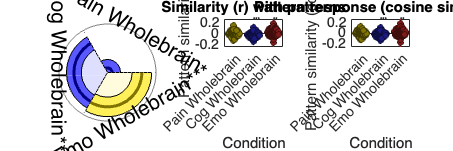

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;


# Manipulation check Rating

# motor contrast

#### motor only :: load dataset

clear all;
close all;

contrast_of_interest = 'motor'

contrast_of_interest = 'motor'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_highlowcue/1stlevel';
contrast_name = {
    'P_VC_STIM_cue_high_gt_low', 'V_PC_STIM_cue_high_gt_low', 'C_PV_STIM_cue_high_gt_low',...% contratss
    'P_VC_STIM_stimlin_high_gt_low', 'V_PC_STIM_stimlin_high_gt_low', 'C_PV_STIM_stimlin_high_gt_low',...
    'P_VC_STIM_stimquad_med_gt_other', 'V_PC_STIM_stimquad_med_gt_other', 'C_PV_STIM_stimquad_med_gt_other',...
    'P_VC_STIM_cue_int_stimlin','V_PC_STIM_cue_int_stimlin', 'C_PV_STIM_cue_int_stimlin',...
    'P_VC_STIM_cue_int_stimquad','V_PC_STIM_cue_int_stimquad','C_PV_STIM_cue_int_stimquad',...
    'motor',... %motor
    'P_simple_STIM_cue_high_gt_low',      'V_simple_STIM_cue_high_gt_low', 'C_simple_STIM_cue_high_gt_low',... % dummay contrasts
    'P_simple_STIM_stimlin_high_gt_low',  'V_simple_STIM_stimlin_high_gt_low', 'C_simple_STIM_stimlin_high_gt_low',...
    'P_simple_STIM_stimquad_med_gt_other','V_simple_STIM_stimquad_med_gt_other', 'C_simple_STIM_stimquad_med_gt_other',...
    'P_simple_STIM_cue_int_stimlin',      'V_simple_STIM_cue_int_stimlin', 'C_simple_STIM_cue_int_stimlin',...
    'P_simple_STIM_cue_int_stimquad',     'V_simple_STIM_cue_int_stimquad','C_simple_STIM_cue_int_stimquad',...
    'P_simple_STIM_highcue_highstim',     'P_simple_STIM_highcue_medstim', 'P_simple_STIM_highcue_lowstim',... % pain events
    'P_simple_STIM_lowcue_highstim',      'P_simple_STIM_lowcue_medstim', 'P_simple_STIM_lowcue_lowstim',...
    'V_simple_STIM_highcue_highstim',     'V_simple_STIM_highcue_medstim', 'V_simple_STIM_highcue_lowstim',... % vicarious events
    'V_simple_STIM_lowcue_highstim',      'V_simple_STIM_lowcue_medstim', 'V_simple_STIM_lowcue_lowstim',...
    'C_simple_STIM_highcue_highstim',    'C_simple_STIM_highcue_medstim', 'C_simple_STIM_highcue_lowstim',... % cognitive events
    'C_simple_STIM_lowcue_highstim',    'C_simple_STIM_lowcue_medstim', 'C_simple_STIM_lowcue_lowstim',...
    'P_VC_CUE_cue_high_gt_low','V_PC_CUE_cue_high_gt_low','C_PV_CUE_cue_high_gt_low',...% cue epoch contrasts
    'P_simple_CUE_cue_high_gt_low','V_simple_CUE_STIM_cue_high_gt_low','C_simple_CUE_cue_high_gt_low',...% cue epoch dummy

};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32347188 bytes
Loading image number:    81
Elapsed time is 3.789429 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7719962  Bit rate: 22.88 bits


#### motor only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:56:25 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
Grouping contiguous voxels:   1 regions


#### motor only :: Plot diagnostics, before l2norm

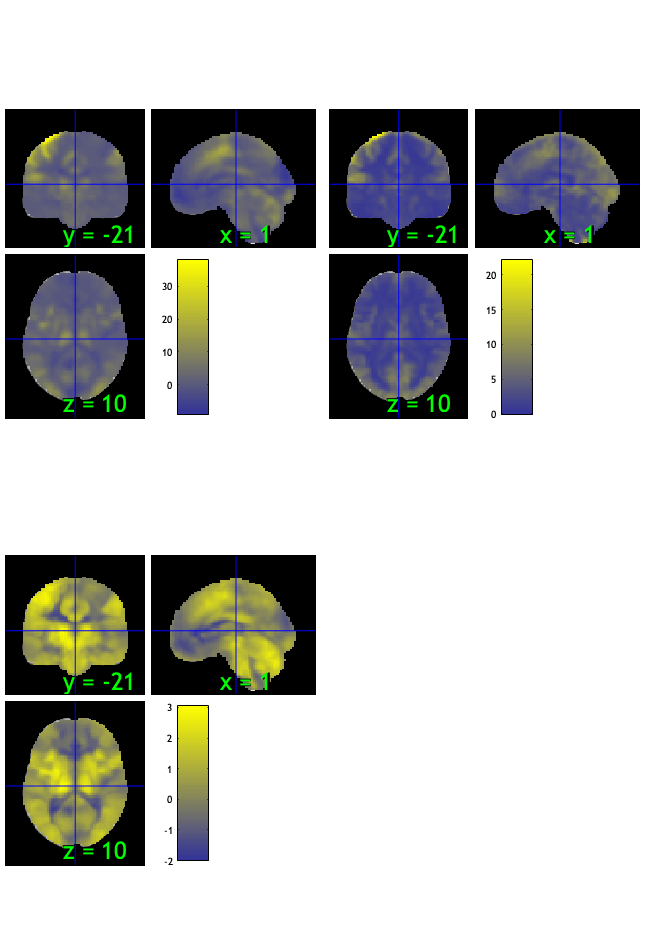

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.04%
Expected 4.05 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 41 
Uncorrected: 5 images		Cases 3 11 22 41 47 

Retained 7 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.68%
Expected 4.05 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 17 
Uncorrected: 5 images		Cases 17 40 51 66 75 

Mahalanobis (cov and corr, q<0.05 corrected):
  2 images 
                               Outlier_count    Percentage
                               

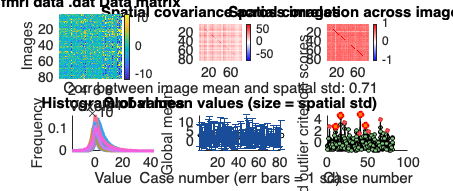

Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.
Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:56:52 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1
 (

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### motor only :: run robfit

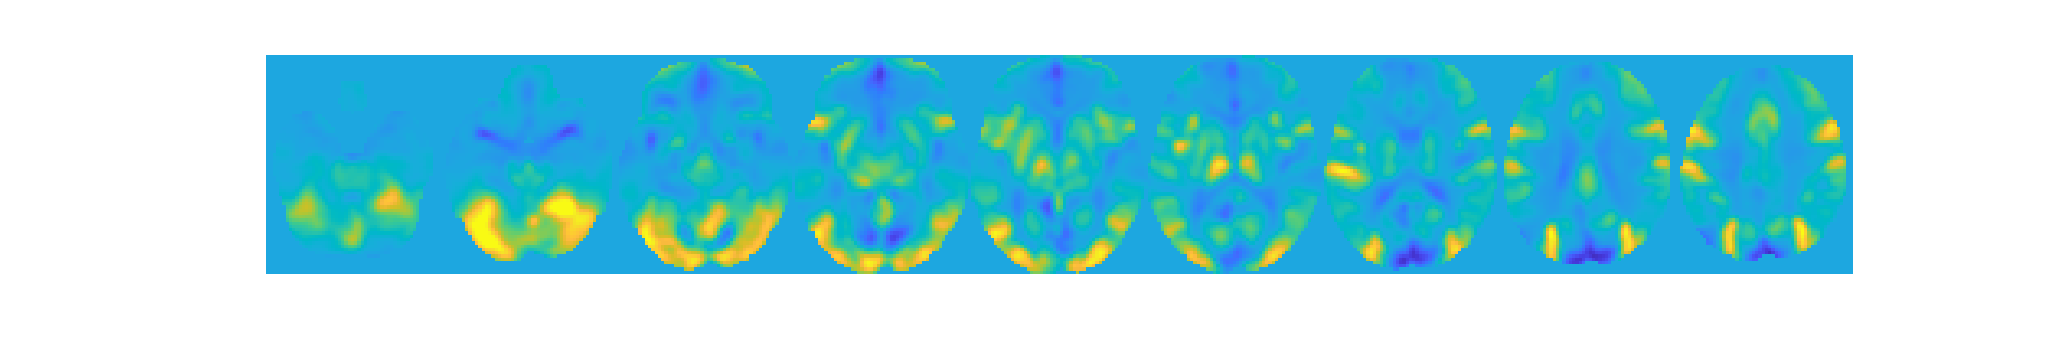

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### motor only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 81


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 77


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0036"    "participants that are outliers:... sub-0044"    "participants that are outliers:... sub-0080"    "participants that are outliers:... sub-0088"



disp(n);

    {'sub-0036'}    {'sub-0044'}    {'sub-0080'}    {'sub-0088'}



#### motor only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### motor only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


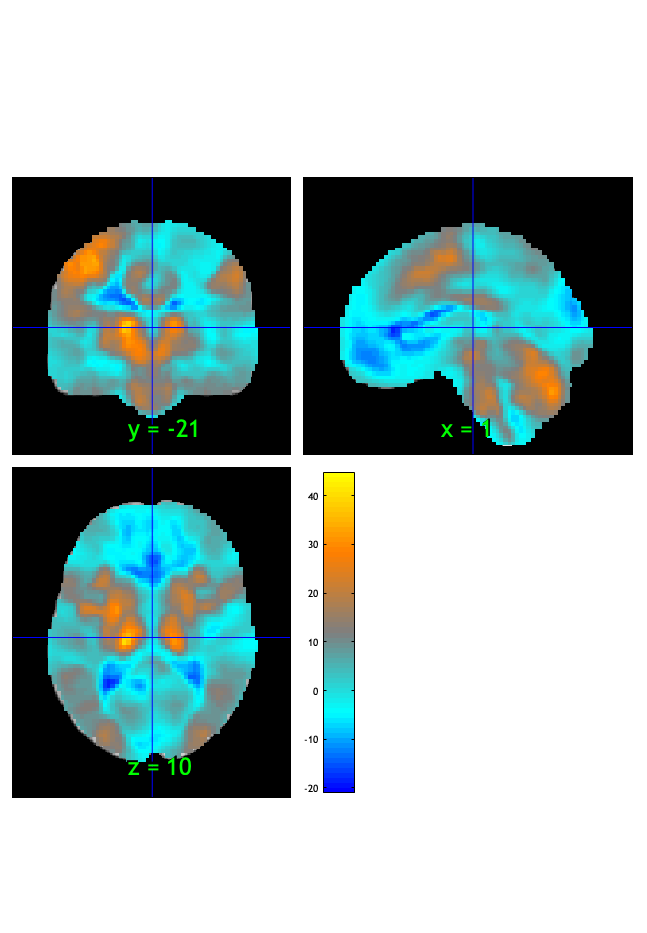

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:56:58 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.041486

Image   1
 10 contig. clusters, sizes   1 to 82754
Positive effect: 66753 voxels, min p-value: 0.00000000
Negative effect: 16083 voxels, min p-value: 0.00000000


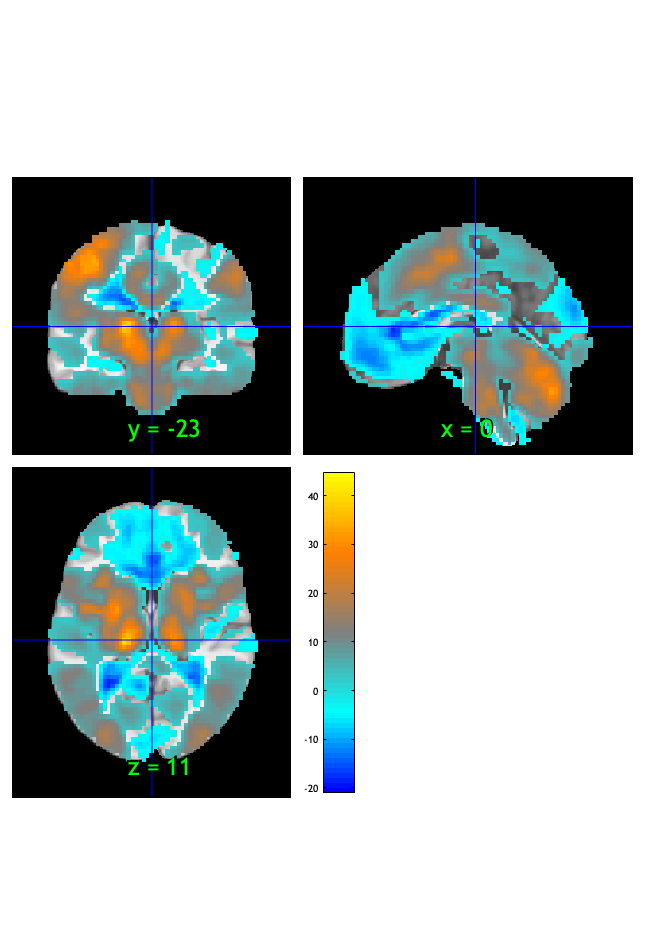

Compressed NIfTI files are not supported.

SPM12: spm_check_registration (v7759)              17:56:59 - 28/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/fmriprep20_template.nii.gz,1


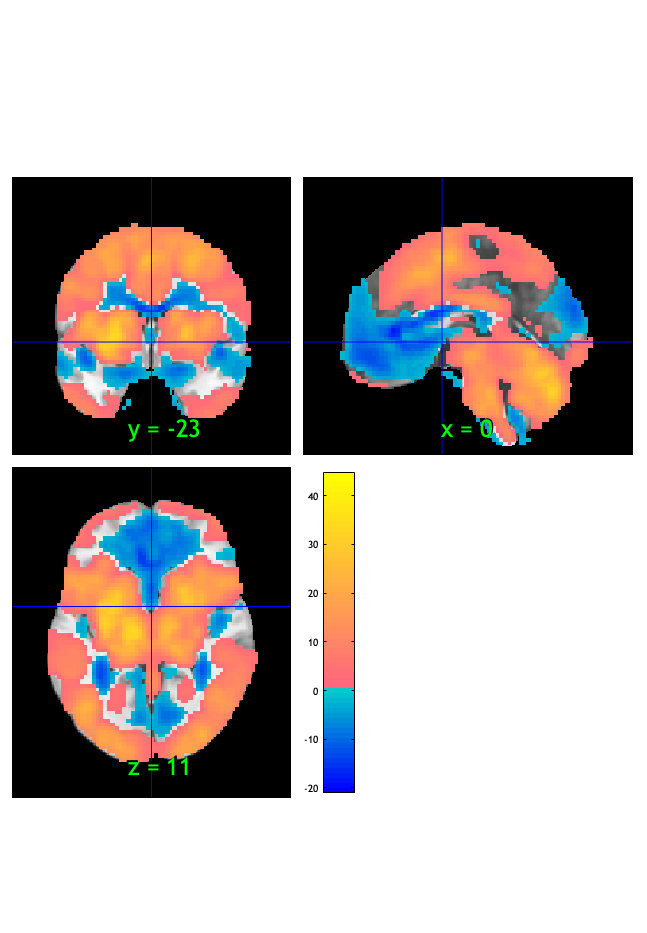

orthviews(fdr_t);

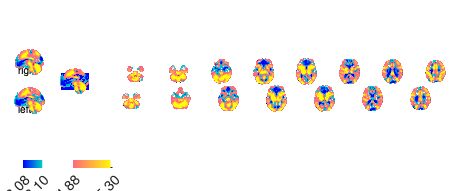

Setting up fmridisplay objects
Compressed NIfTI files are not supported.
sagittal montage: 2077 voxels displayed, 80759 not displayed on these slices
sagittal montage: 2071 voxels displayed, 80765 not displayed on these slices
sagittal montage: 1957 voxels displayed, 80879 not displayed on these slices
axial montage: 15350 voxels displayed, 67486 not displayed on these slices
axial montage: 16686 voxels displayed, 66150 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;



#### motor only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high   
    _________    ______________    __________    ________________

    -0.33403     {'trait'     }     0.38523      {'movements'   }
    -0.32385     {'positive'  }     0.35892      {'execution'   }
    -0.32292     {'negative'  }     0.35482      {'hand'        }
    -0.30972     {'age'       }     0.32915      {'motor'       }
    -0.29693     {'personal'  }     0.32391      {'visual'      }
    -0.29204     {'depression'}      0.3129      {'finger'      }
    -0.28797     {'emotion'   }     0.28624      {'sensorimotor'}
    -0.28769     {'disorder'  }     0.28597      {'action'      }
    -0.28606     {'affect'    }     0.28405      {'hands'       }
    -0.28267     {'person'    }   

motor only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0190	-4.5393	0.0000	1.0000	***
Cog Wholebrain	0.0315	13.0554	0.0000	1.0000	***
Emo Wholebrain	-0.0102	-2.5237	0.0136	1.0000	*
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.019015     0.0041886    -4.5397    1.9632e-05    -0.50441
    {'Cog Wholebrain' }     0.031529     0.0024132     13.065    2.2204e-15      1.4517
    {'Emo Wholebrain' }    -0.010242     0.0040571    -2.5244      0.013569    -0.28049



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [19.0006 20.0006 21.0006]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.014386     0.0038038     -3.782    0.00029872    -0.42022
    {'Cog Wholebrain' }     0.028578     0.0022056     12.957    2.2204e-15      1.4396
    {'Emo Wholebrain' }    -0.012545     0.0037215    -3.3711     0.0011552    -0.37456



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {81×3 cell}
        text_han: {81×3 cell}
       point_han: {81×3 cell}
    star_handles: [22.0006 23.0006 24.0006]


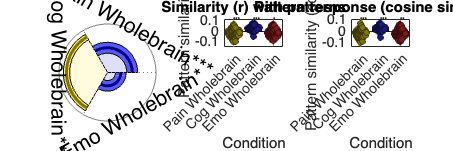

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;


% save html
% pubdir = pwd;
% pubfilename = '6cond_cueeffect_contrast.mlx';
% 
% p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
%   'format', 'html', 'outputDir', pubdir, ...
%   'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
% htmlfile = publish(pubfilename, p);